# **Repeated Trials and Galton Board**

## Repeated Trials

Suppose there are 3 fair dice. Now throw them together. Let's calculate the probability of getting different numbers in sum.

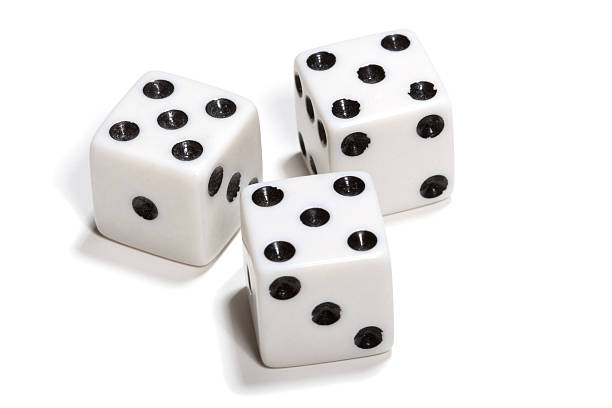

#### Step 1: Set the probability for each number will get when throwing 1 dice

#### Step 2: Use conv to calculate the probability for throwing 2 dice. 

#### Step 3: Do another convolution to calculate the probability for throwing 3 dice.

#### Step 4: Display the table of results.

#### Step 5: Plot the result. 

% Step 1Set the probability for each number will get when throwing 1 dice.
D1 = 1/6*ones(1,6);
D2 = D1;
D3 = D2;
% Use conv to calculate the probability for throwing 2 dice.
d1d2 = conv(D1,D2,'full');
% Do another convolution to calculate the probability for throwing 3 dice.
d = conv(d1d2,D3,'full');
% Display the table of results.
Probabilty = [d';sum(d)];
Combinations = zeros(1,16)';
for i = 1:6
    for j = 1:6
        for k = 1:6
            Combinations(i+j+k-2) = 1 + Combinations(i+j+k-2);
        end
    end
end
Combinations = [Combinations;sum(Combinations)];
Totals = [3:18,"Totals"]';
disp(table(Totals,Combinations, Probabilty))

     Totals     Combinations    Probabilty
    ________    ____________    __________

    "3"               1         0.0046296 
    "4"               3          0.013889 
    "5"               6          0.027778 
    "6"              10          0.046296 
    "7"              15          0.069444 
    "8"              21          0.097222 
    "9"              25           0.11574 
    "10"             27             0.125 
    "11"             27             0.125 
    "12"             25           0.11574 
    "13"             21          0.097222 
    "14"             15          0.069444 
    "15"             10          0.046296 
    "16"              6          0.027778 
    "17"              3          0.013889 
    "18"              1         0.0046296 
    "Totals"        216                 1 



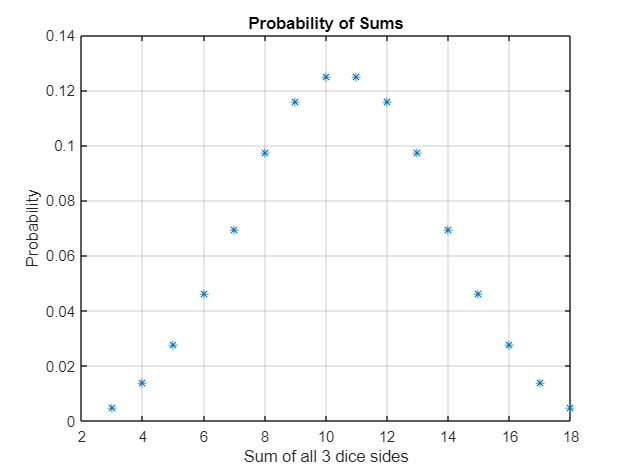

% Plot the result.
plot ([3:1:18],d,'*');
grid on;
xlabel('Sum of all 3 dice sides');
ylabel('Probability');
title('Probability of Sums');

## Galton Board Simulation

Let's simulate the Galton’s Board process using MATLAB.

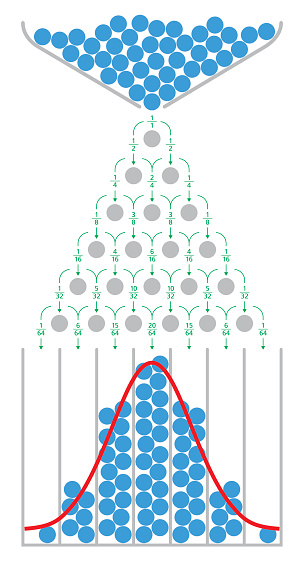

#### Step 1: Input:* n = #* peg rows, *m = #* simulations, output is a plot. Set up counters for each location:

#### Step 2:  Do m simluations, p tracks the location of the ball; starts at 1.

#### Step 3: Compute the expected values according to the formula.

#### Step 4: Produce a plot of simulation against probabilities. Note: divide simulations by total number of balls.

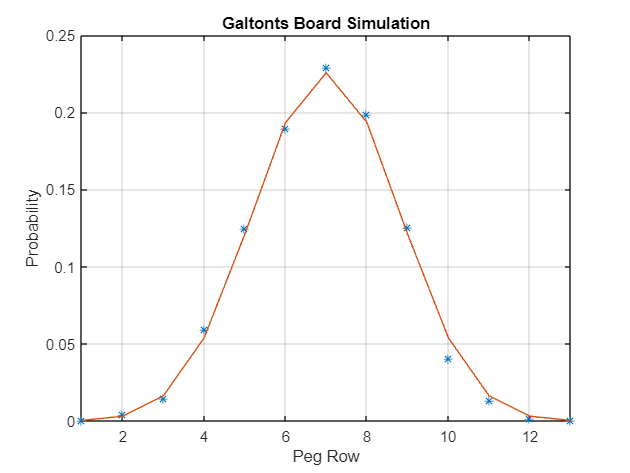

% Input: n = # peg rows, m = # simulations, output is a plot. 
% Set up counters for each location.
n = 12; m = 3000;
count = zeros(1,n+1);
% Do m simluations, p tracks the location of the ball; starts at 1.
for k=1:m 
  p = 1; 
  for j=1:n 
      if rand > 0.5
          p = p+1; % at each peg go right (p=p+1) or left (p=p)
      end
  end
  count(p) = count(p)+1; % ball at bottom, location p, add to count(p)
end
% Compute the expected values according to the formula.
count2 = zeros(1,n+1);
for j=0:n
  count2(j+1) = factorial(n)/(2^n*factorial(j)*factorial(n-j));
end
% Produce a plot of simulation against probabilities. 
% Note: divide simulations by total number of balls.
x = 1:n+1; 
plot(x,count/m,'*',x,count2,'-')
grid on;
title('Galtonts Board Simulation');
ylabel('Probability');
xlabel('Peg Row');
xlim([1,n+1])